# Optimización no lineal multidimensional sin restricciones utilizando el método del gradiente descendente, **con t variable**, en MATLAB

**Profesor:** PhD. Marlon E. Moscoso Martínez

% Limpiar la consola, variables y cerrar figuras
clc; clear; close all; 

## Definir la función objetivo y su gradiente

% Función objetivo f(x1, x2)
f = @(x) (x(1) - 2)^2 + (x(2) - 3)^2 + exp(x(1)^2 + x(2)^2);

% Gradiente de f
grad_f = @(x) [2*(x(1) - 2) + 2*x(1)*exp(x(1)^2 + x(2)^2);
               2*(x(2) - 3) + 2*x(2)*exp(x(1)^2 + x(2)^2)];
% Mostrar la ecuación de la función
disp('Función a Minimizar: f(x_1, x_2) = (x_1 - 2)^2 + (x_2 - 3)^2 + e^{x_1^2 + x_2^2}')

Función a Minimizar: f(x_1, x_2) = (x_1 - 2)^2 + (x_2 - 3)^2 + e^{x_1^2 + x_2^2}


## Paso 1: Inicializar el algoritmo

% Punto inicial x0
x0 = [0; 0]; % Iniciamos en el origen [x1, x2]
% Parámetros del algoritmo
delta = 1e-6; % Tolerancia para la convergencia
max_iter = 100; % Número máximo de iteraciones
iter = 0;

% Inicializar los errores
error_1 = delta +1; % Error ||x_{k+1} - x_k||
error_2 = delta +1; % Error ||grad_f(x_{k+1})||
x_k = x0;
x_hist = x_k';

% Inicializar tabla de resultados por iteración
tabla_it = [];

## Implementación del Método del Gradiente Descendente

while (error_1 > delta || error_2 > delta) && iter < max_iter
    iter = iter +1;
    %% Paso 2: gradiente en el punto actual y tasa de aprendizaje
    gradiente = grad_f(x_k);
    ft = @(t) f(x_k - t * gradiente); % función unidimensional 
    t_k = busqueda_dicotomica(ft,0,0.1,delta,max_iter) % Búsqueda dicotómica para encontrar el t óptimo, intervalo inicial I=[0, 0.1]
    %% Paso 3: actualizar el punto
    x_k_plus_1 = x_k - t_k * gradiente;

    %% Calcular errores
    error_1 = norm(x_k_plus_1 - x_k); % Diferencia entre puntos sucesivos
    error_2 = norm(grad_f(x_k_plus_1)); % Tamaño del gradiente

    %% Guardar resultados iteración en tabla
    tabla_it = [tabla_it; iter, x_k(1), x_k(2), f(x_k), error_1, error_2];

    % Actualizar x_k y guardar en el historial
    x_k = x_k_plus_1;
    x_hist = [x_hist; x_k']; % Guardar el nuevo punto en el historial
end

t_k = 0.1000

t_k = 0.0797

t_k = 0.0953

t_k = 0.0465

t_k = 0.0836

## Imprimir resultados

% Mostrar la tabla con las iteraciones
T = array2table(tabla_it, 'VariableNames', {'Iteración','x_1', 'x_2', 'f(x_1, x_2)', 'Error_1', 'Error_2'});
disp(T);

    Iteración      x_1        x_2      f(x_1, x_2)     Error_1       Error_2  
    _________    _______    _______    ___________    __________    __________

        1              0          0          14          0.72111        3.3431
        2            0.4        0.6      10.002          0.26635    1.2008e-05
        3        0.54774    0.82161      9.5058       1.1444e-06    8.1844e-06
        4        0.54774    0.82161      9.5058       3.8038e-07    1.4732e-06
        5        0.54774    0.82161      9.5058       1.2315e-07    6.9961e-07



% Mostrar la solución
x_opt = x_k;
fprintf('Solución óptima encontrada en la iteración %d: (x_1, x_2) = (%.4f, %.4f)\n', iter, x_opt(1), x_opt(2));

Solución óptima encontrada en la iteración 5: (x_1, x_2) = (0.5477, 0.8216)


fprintf('Valor mínimo de f(x_1, x_2) = %.4f', f(x_opt));

Valor mínimo de f(x_1, x_2) = 9.5058

## Visualización gráfica de la función objetivo y la solución

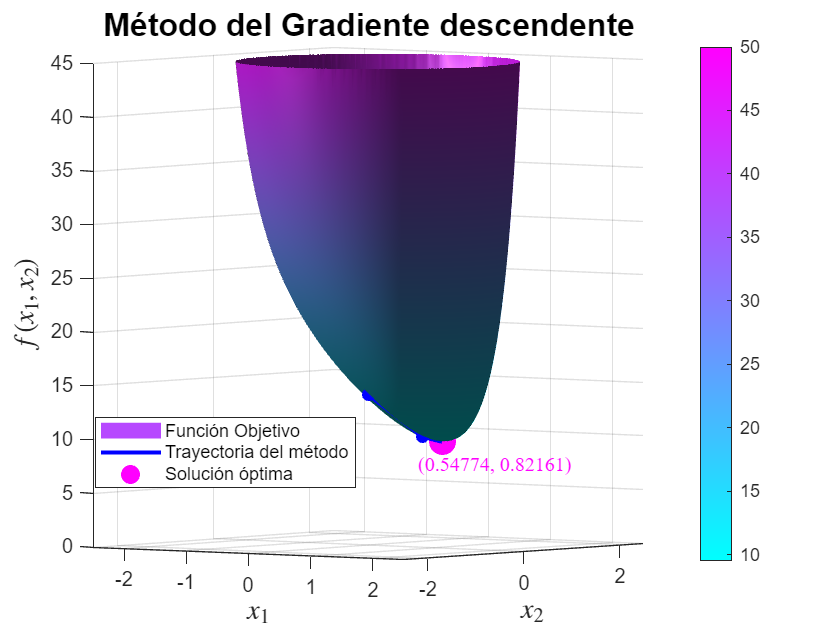

% Gráfico 3D 
[x_vals, y_vals] = meshgrid(-2.5:0.05:2.5, -2.5:0.05:2.5); % Generar malla
f_vals = (x_vals - 2).^2 + (y_vals - 3).^2 + exp(x_vals.^2 + y_vals.^2); % Evaluar f en la malla
% Limitar el valor máximo de f(x_1, x_2) para mejorar visualización
f_vals(f_vals > 50) = 50;
% Graficar la función objetivo
figure;
surf(x_vals, y_vals, f_vals, 'EdgeColor','none'); % Gráfico superficie sin bordes
hold on;

% Añadir detalles
shading interp; % Interpolación de colores para suavizar la superficie
colormap("cool"); 
colorbar; % Mostrar barra de colores
lighting phong; % Mejorar iluminación de la superficie
camlight headlight; % Añadir luz de cámara

% Rotar la vista para apreciar mejor el mínimo
view([397.7 2.5]); % Ajustar ángulo de vista para apreciar el mínimo

% Ajustar los límites de los ejes para mejorar visualización
xlim([-2.5, 2.5]);
ylim([-2.5, 2.5]);
zlim([0, 45]); 

% Dibujar la trayectoria del método
z_vals_hist = arrayfun(@(i) f(x_hist(i, :)'), 1:size(x_hist, 1)); % Evaluar f en puntos del historial
plot3(x_hist(:, 1), x_hist(:, 2), z_vals_hist, '-b', 'LineWidth', 2); % Línea de trayectoria
plot3(x_hist(:, 1), x_hist(:, 2), z_vals_hist, 'bo', 'MarkerSize', 6, 'MarkerFaceColor', 'b'); % Puntos iterativos

% Marcar la solución óptima en el gráfico
plot3(x_opt(1), x_opt(2), f(x_opt), 'mo', 'MarkerSize', 13, 'MarkerFaceColor','m'); 
text(x_opt(1), x_opt(2) -0.5, f(x_opt)-2, ['(', num2str(x_opt(1)), ', ', num2str(x_opt(2)), ')'],"FontSize",10,"Color",'m','FontName','Times New Roman');

% Etiquetas de los ejes con latex
xlabel('$x_1$', 'Interpreter','latex','FontSize',14,'FontWeight','bold');
ylabel('$x_2$', 'Interpreter','latex','FontSize',14,'FontWeight','bold');
zlabel('$f(x_1, x_2)$', 'Interpreter','latex','FontSize',14,'FontWeight','bold');
% Añadir título descriptivo con latex
title('Método del Gradiente descendente','FontSize',16,'FontWeight','bold');
legend(["Función Objetivo", "Trayectoria del método","", "Solución óptima"], "Position", [0.1418 0.2429 0.2536, 0.0774])
grid on;
hold off;

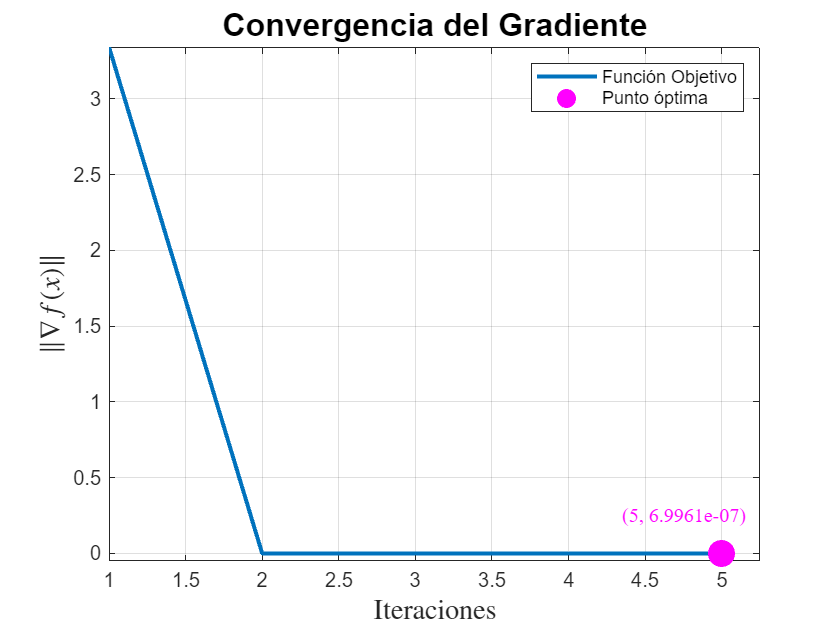

% Graficar Convergencia del Gradiente
figure;
plot(tabla_it(:,1),tabla_it(:,6),'LineWidth',2);
hold on;
% Marcar la solución óptima en el gráfico
plot(tabla_it(end,1), tabla_it(end,6), 'mo', 'MarkerSize', 13, 'MarkerFaceColor','m'); 
text(tabla_it(end,1)-0.65, tabla_it(end,6)+0.25, ['(', num2str(tabla_it(end,1)), ', ',  num2str(tabla_it(end,6)), ')'],"FontSize",10,"Color",'m','FontName','Times New Roman');
% Etiquetas de los ejes con latex
xlabel('Iteraciones', 'Interpreter','latex','FontSize',14,'FontWeight','bold');
ylabel('$\|\nabla f(x)\|$', 'Interpreter','latex','FontSize',14,'FontWeight','bold');
title('Convergencia del Gradiente','FontSize',16,'FontWeight','bold');
legend(["Función Objetivo", "Punto óptima"])
grid on;
hold off;
xlim([1, tabla_it(end,1)+0.25]);
ylim([-0.05, tabla_it(1,6)]);